# LABORATORIO DE FUNDAMENTOS DE CONTROL: MATLAB

#### ALEJANDRO ANTONIO CASTILLO GIL              201722422-3744  

#### DAVID FRANCO OSPINA                                      201730550-3744

#### JUAN CAMILO GIRALDO GARCIA                       201731702-3744

- Implemente los siguientes polinomios y halle el producto entre ellos.

         
$$a(s)=s 2-20.6$$


         
$$b(s)=s 2 +19.6 s+151.2$$
 

a=[1 0 -20.6];
b=[1 19.6 151.2];
x=conv(a,b);
disp(x);

   1.0e+03 *

    0.0010    0.0196    0.1306   -0.4038   -3.1147



          2.   Escriba las siguiente matrices.

A=[1.56 2.45 -3.11 4.10;
   3.22 1.00 2.50 3.25;
   -1.00 2.00 -0.66 0.05;
   0.23 0.90 1.00 0.33]

A =     1.5600    2.4500   -3.1100    4.1000
    3.2200    1.0000    2.5000    3.2500
   -1.0000    2.0000   -0.6600    0.0500
    0.2300    0.9000    1.0000    0.3300


B=[1.2 10 15 0;
   3 5.5 2 2.8;
   4 6.8 7 0.78;
   0.89 -0.16 1.24 25]

Determine la matriz transpuesta e inversa de cada una.

A_inv=inv(A)
B_inv=inv(B)
A_trans=transpose(A)

B =     1.2000   10.0000   15.0000         0
    3.0000    5.5000    2.0000    2.8000
    4.0000    6.8000    7.0000    0.7800
    0.8900   -0.1600    1.2400   25.0000


A_inv =   -44.7302   80.2887  129.2018 -254.5593
  -18.6694   33.4703   54.2921 -105.9049
   14.1660  -25.5202  -41.3099   81.5925
   39.1648  -69.9075 -112.9376  222.0322


B_inv =    -0.1984   -0.2501    0.4943    0.0126
    0.0986    0.3947   -0.3180   -0.0343
    0.0168   -0.2431    0.1724    0.0218
    0.0069    0.0235   -0.0282    0.0382


A_trans =     1.5600    3.2200   -1.0000    0.2300
    2.4500    1.0000    2.0000    0.9000
   -3.1100    2.5000   -0.6600    1.0000
    4.1000    3.2500    0.0500    0.3300


B_trans=transpose(B)

B_trans =     1.2000    3.0000    4.0000    0.8900
   10.0000    5.5000    6.8000   -0.1600
   15.0000    2.0000    7.0000    1.2400
         0    2.8000    0.7800   25.0000


Halle $(A*B)$ ,  $(A+B)$ , $A^2$.

M=A*B

M =     0.4310    7.2710   11.6140  106.9342
   19.7565   54.1800   71.8300   86.0000
    2.2045   -3.4960  -15.5580    6.3352
    7.2697   13.9972   12.6592   11.5500


S=A+B

S =     2.7600   12.4500   11.8900    4.1000
    6.2200    6.5000    4.5000    6.0500
    3.0000    8.8000    6.3400    0.8300
    1.1200    0.7400    2.2400   25.3300


Square=A^2

Square =    14.3756    3.7420    7.4260   15.5560
    6.4907   16.8140   -5.9142   17.6495
    5.5515   -1.7250    8.5956    2.3835
    2.3327    3.7605    1.2047    4.0269


       3.  . Para la siguiente función de transferencia, 

G=tf([1 3.5 1.5],[1 3 2 0]);
% (s+0.5)(s+3)
% -----------
% s(s+1)(s+2)
display(G)


G =
 
  s^2 + 3.5 s + 1.5
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.



Halle su respuesta ante un escalón unitario en lazo cerrado con realimentación unitaria, por medio de comandos.

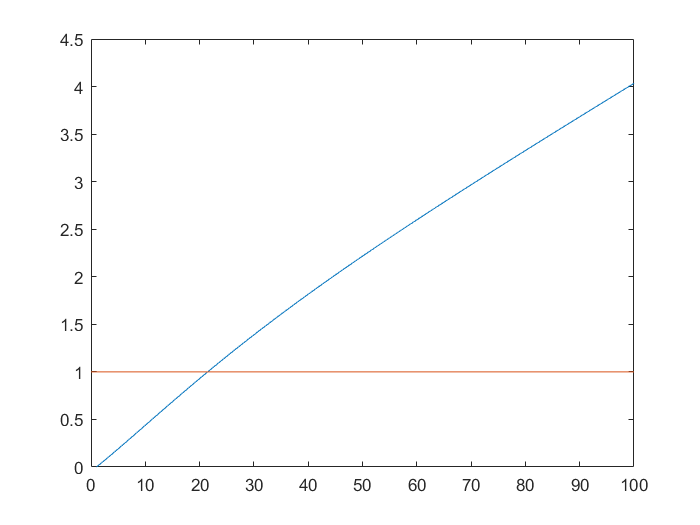

R=step(G);
figure(1)
plot(R)
xlim([0 100])
hold on
fplot(heaviside(sym(1)))

y mediante el ambiente Simulink.

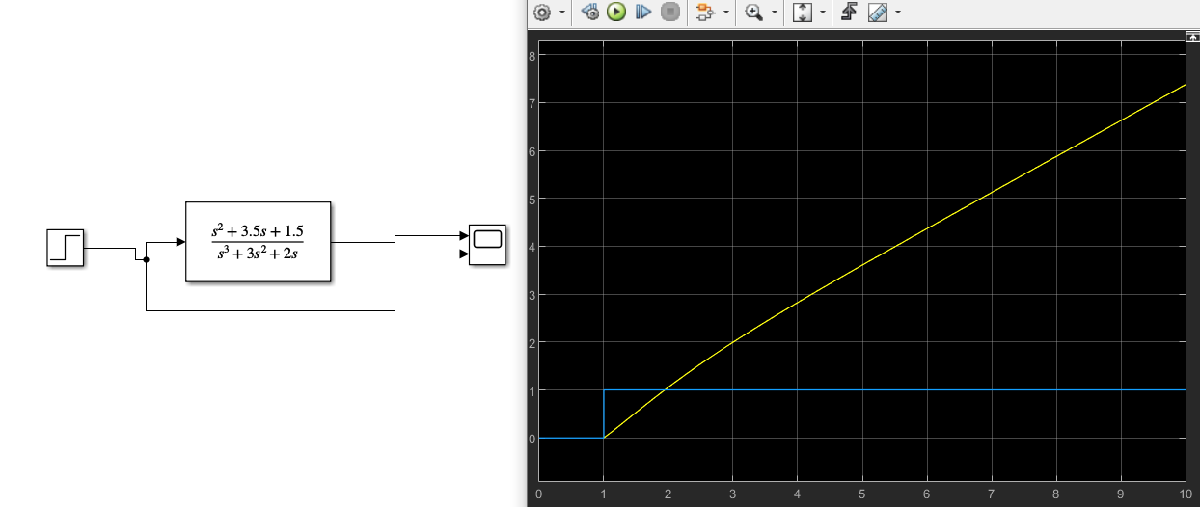

    4.  Importe al Workspace de Matlab el archivo “datos3.txt” .

Muestras

Muestras =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


Salida

Salida =     0.0006
    0.0003
    0.0006
    0.0009
    0.0006
    0.0006
    0.0012
         0
   -0.0006
    0.0003


Grafique los datos de este archivo:

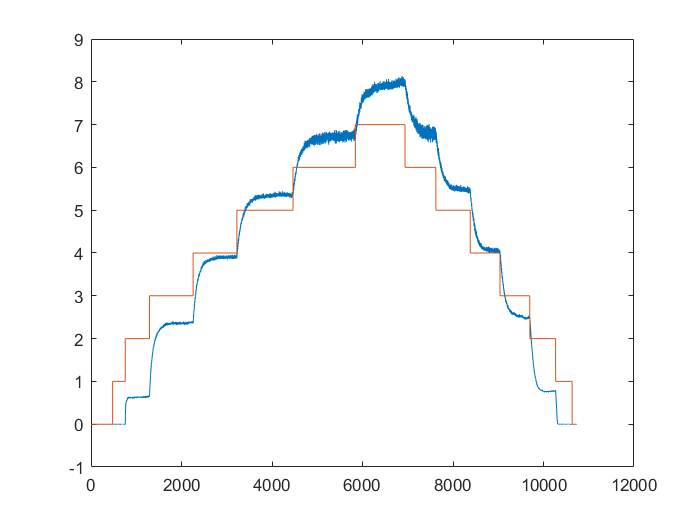

figure(2)
plot(Muestras,Salida);
hold on
plot(Muestras,Escalon);

       4.1  Obtenga la gráfica correspondiente para un rango de 2800 a 4500 muestras.

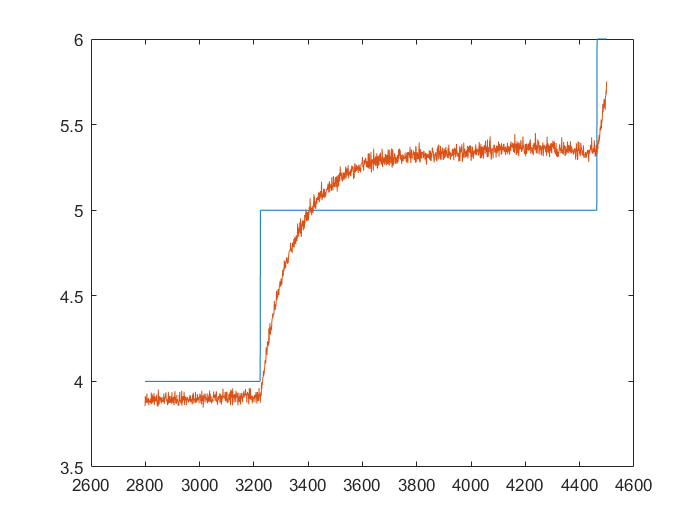

x=Muestras(2800:4500);
y=Escalon(2800:4500);
z=Salida(2800:4500);
figure(3)
plot(x,y);
hold on
plot(x,z);

    4.2    Represente la gráfica obtenida anteriormente para una escala de tiempo en segundos, asuma un tiempo de muestreo “Ts” de 1ms.

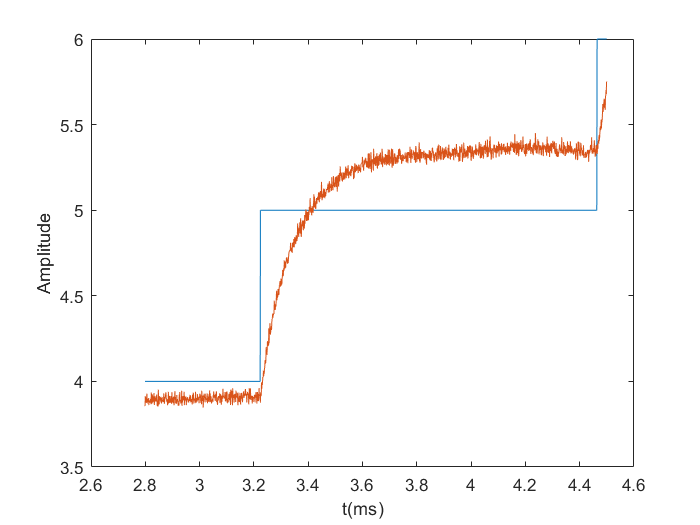

xm=x./1000;
figure(4)
plot(xm,y);
hold on
plot(xm,z);
xlabel("t(ms)");
ylabel("Amplitude");